# 1.2.07. Построение графиков

**Лекция**

## Построение нескольких графиков в одном окне

Чтобы в одном графическом окне создать несколько отдельных рисунков, необходимо прибегнуть к функции `subplot`, которая позволяет разбить графическое окно на несколько прямоугольных областей одинакового размера, расположенных подобно элементам матрицы:

`    subplot``(row, col, cur)`

Первые два аргумента задают количество рядов (`row`) и колонок (`col`), третий параметр объявляет порядковый номер поля, в котором будет строиться очередной график.

Чтобы впоследствии обращаться к желаемому полю (например чтобы построить график в конкретной из них), можно создать переменную типа `Axes`, которая будет содержать ссылку на это поле:

`    Переменная1 = ``subplot``(row, col, cur);`

Впоследитвии к ней можно обращаться из функций построения графиков, таких как `plot`, `scatter`, `histogram` и др: 

`    plot``(Переменная1, XData, Ydata, ...)`

Пример:

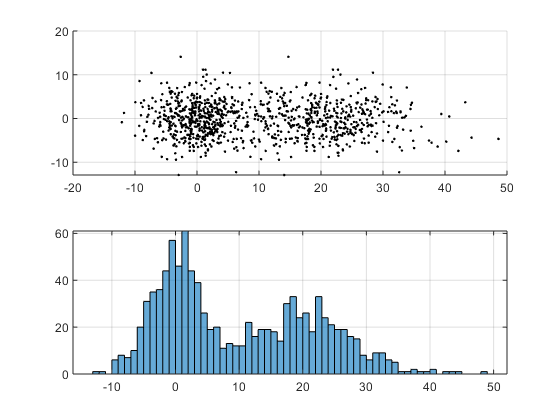

X1 = 4* randn(500, 2);          % Формируем данные для рисования
X2 = [X1; [2*(X1(:,1) + 10),X1(:,2)]];

a1 = subplot(2, 1, 1);      % Создаем поле a1 
a2 = subplot(2, 1, 2);      % Создаем поле a2
scatter(a1, X2(:,1), X2(:,2), '.k');    % Рисуем точечный график на поле a1 
histogram(a2,X2(:,1),'BinWidth',1);     % Рисуем гистограмму на поле a2 с шириной столбцов 1.

grid(a1,'on')   %   отображение сетки в поле a1
grid(a2,'on')   %   отображение сетки в поле a2

Более подробно о возможностях функции subplot можно узнать, набрав в командной строке

## Редактирование графиков с помощью Property Inspector

Чтобы задать графику желаемый формат, свойства и пр. можно воспользоваться окном Property Inspector. Проиллюстрируем его работу на примере. Построим график без свойств с помощью функции `plot`:

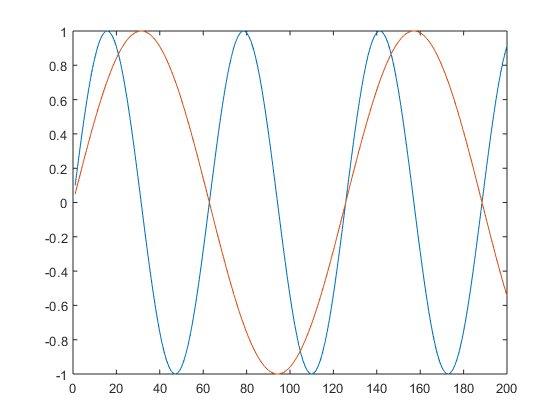

X3 = (1:200)';
figure     %    Создаем новый график
plot(X3, [sin(X3/10),sin(X3/20)]) 

Откроем график в окне, вызываем Property Inspector:

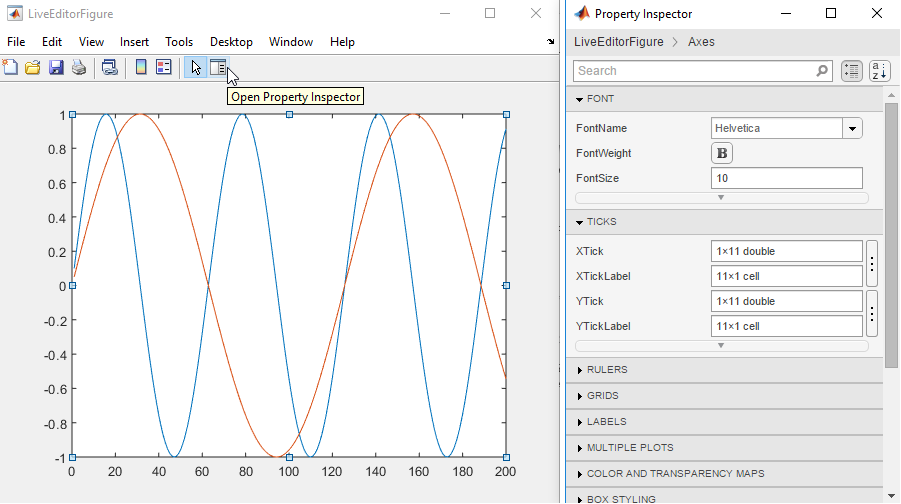

В появившемся окне Property Inspector можно вручную менять свойства окна, осей и линий. 

Чтобы сделать цвет окна - белым следует изменить соответствующее свойство:

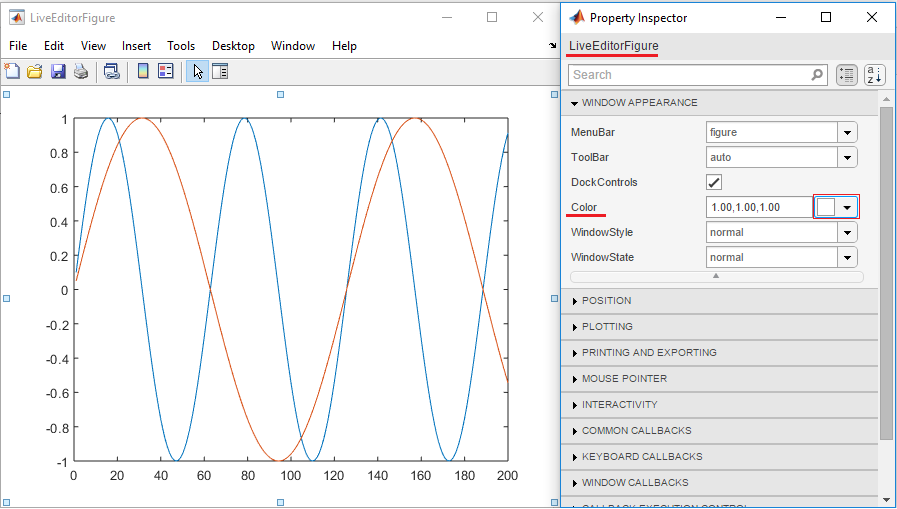 

Например, чтобы изменить шрифт и размер подписей осей и добавить сетку следует редактировать свойства поля (Axes):

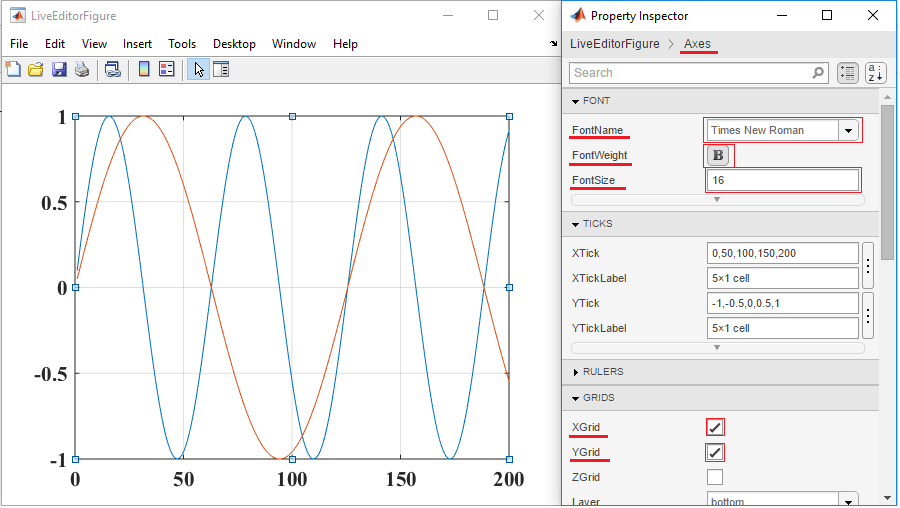

Для того, чтобы изменить, например, цвет, толщину и тип линии следует изменить свойства линий:

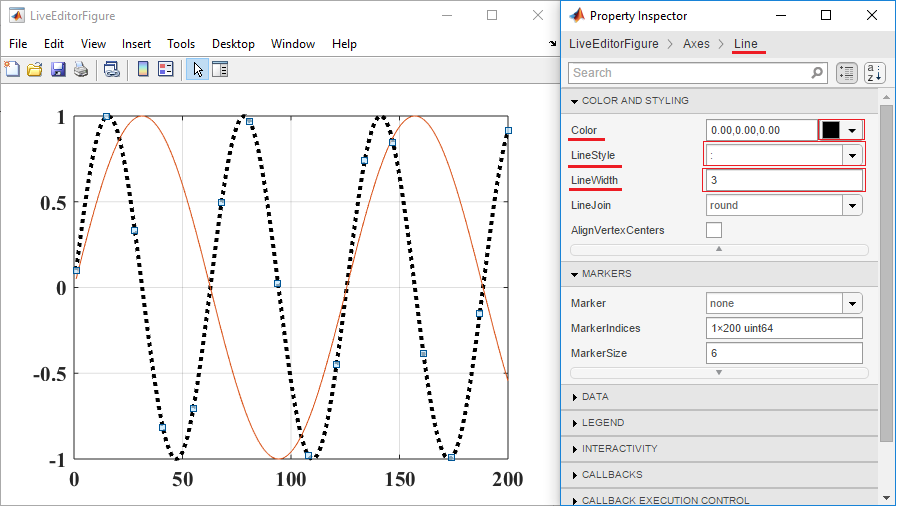

## Рисование графиков: структура отображения

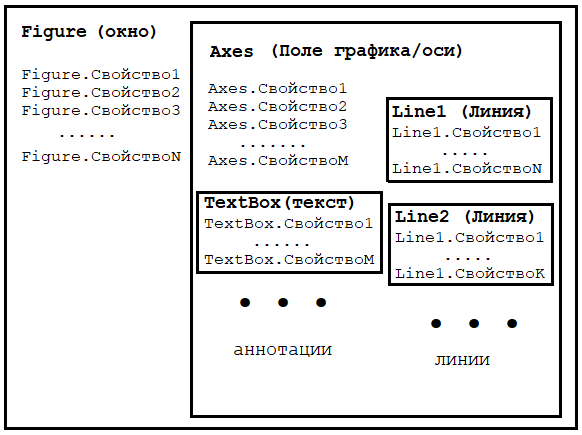

## Кастоимизация фигуры и осей

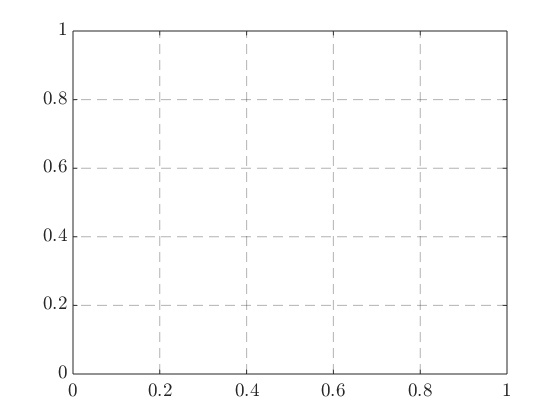

F1 = figure;
    F1.Color = 'white';
    
    A1 = axes;
        A1.Box = 'on';
        A1.TickLabelInterpreter = 'latex';
        A1.FontName = 'Times New Roman';
        A1.FontSize = 14;
        A1.XGrid = 'on';
        A1.YGrid = 'on';
        A1.GridColor = '[0,0,0]';
        A1.GridLineStyle = '--';
        A1.GridAlpha = 0.3;

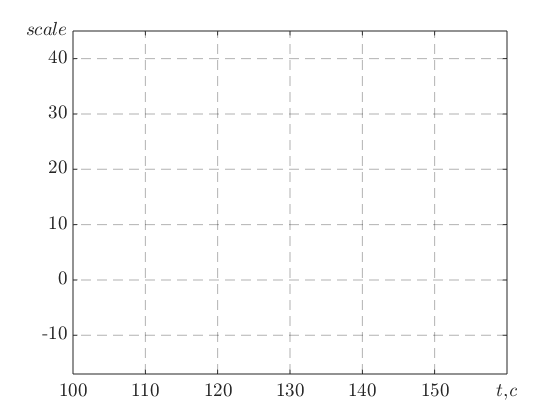

F2 = figure('Color','white');

    A2 = axes( 'Box','on','TickLabelInterpreter', 'latex', ...
         'FontName','Times New Roman', 'FontSize', 14, 'XGrid', 'on', 'YGrid', 'on', ...
         'GridColor', '[0,0,0]', 'GridLineStyle', '--', 'GridAlpha', 0.3); 
     
        A2.XLim = [100,160];
        A2.XTick = [100, 110, 120, 130, 140, 150, 160];
        A2.XTickLabel = {100 110 120 130 140 150 '$t$,\textit{c}'};
        
    set(A2, 'Ylim',[-17,45], ...
            'YTick', [-10, 0, 10, 20, 30, 40, 45],...
            'YTickLabel', {-10 0 10 20 30 40 '$scale$'} )

## Кастомизированная постройка графиков

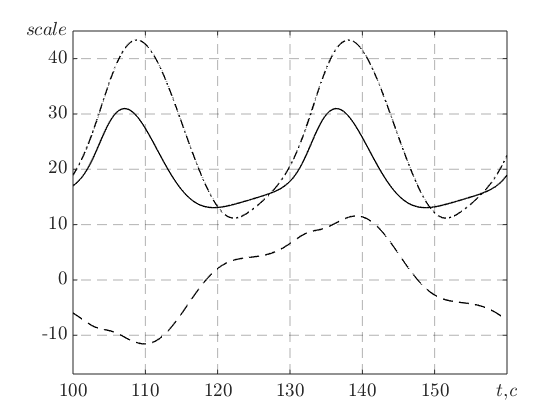

        hold on
            load('data07_vis_lecture.mat');
            P1 = plot(Data(:,1), Data(:,2));
                P1.LineWidth = 1;
                P1.LineStyle = '-';
                P1.Color = 'black';
                
            P2 = plot(Data(:,1),Data(:,3), ...
                'LineWidth', 1, 'LineStyle', '--', 'Color', [0,0,0]);
            
            P3 = plot(Data(:,1), Data(:,4));
                set(P3, 'LineWidth', 1, 'LineStyle', '-.', 'Color', 'black');

                 
        hold off       

## Добавление аннотаций

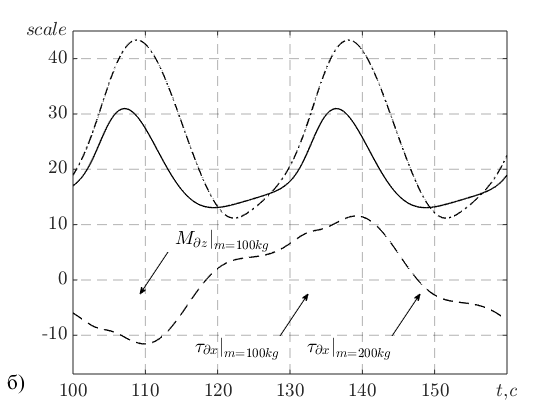

        Text1 = annotation(F2,'textbox');
            Text1.EdgeColor = 'None';
            Text1.Interpreter = 'tex'; %поддерживает русский
            Text1.String = 'б)';            
            Text1.FontName = 'Times New Roman';
            Text1.FontSize = 16;            
            Text1.Position = [0, 0.0, 0.13, 0.13]; 
            
        Arrow1 = annotation('textarrow');
            Arrow1.Interpreter = 'latex';
            Arrow1.String = '$\left. \tau_{\partial x} \right|_{m = 100kg}$';
            Arrow1.Color = 'black';
            Arrow1.FontName = 'Times New Roman';
            Arrow1.FontSize = 14;
            Arrow1.HeadLength = 5;
            Arrow1.HeadWidth = 5;
            Arrow1.LineWidth = 0.4;            
            Arrow1.Position = [0.5, 0.2, 0.05, 0.1] ;
            
        Arrow2 = annotation('TextArrow', 'Interpreter', 'latex', ...
            'String', '$\left. \tau_{\partial x} \right|_{m = 200kg}$' , ...
            'Color', [0,0,0], 'FontAngle', 'italic', 'FontName','Times New Roman', 'FontSize', 14,...
            'HeadLength', 5, 'HeadWidth', 5, 'LineWidth', 0.4,...
            'Position',[0.7, 0.2, 0.05, 0.1]);
        
        Arrow3 = annotation('TextArrow');
            set(Arrow3, 'Interpreter', 'latex', 'String',...
                '$\left. M_{\partial z} \right|_{m = 100kg}$' ,...
                'Color', [0,0,0], 'FontAngle', 'italic', 'FontName','Times New Roman', 'FontSize', 14, ...
                'HeadLength', 5, 'HeadWidth', 5, 'LineWidth', 0.4,...
                'Position', [0.3, 0.4, -0.05, -0.1 ]);

## Редактирование и сохранение графика

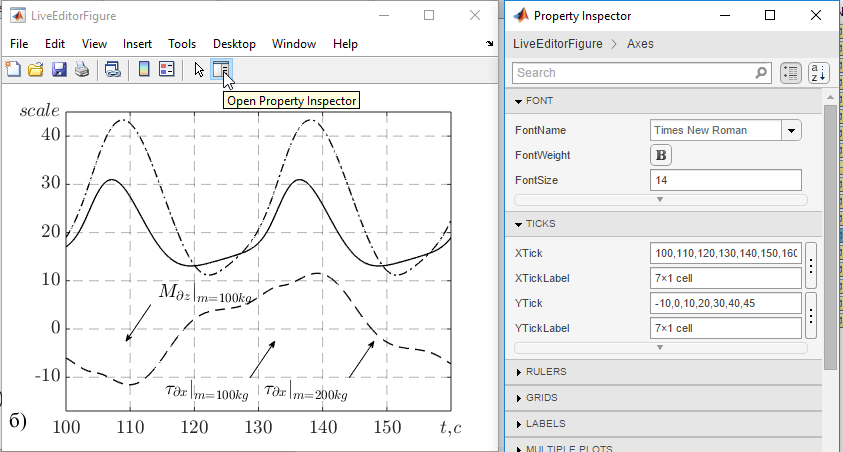

C помощью Property Inspector размещаем стрелки